# Biochemical Reaction Networks

Biochemical reactions are essentially chemical reactions that takes place in a cell. Specifically, it involves the conversion of one molecule to another. This can be on a larger scale, like glycolysis - converting glucose into pyruvate, or, it can be on a small scale, like adding a phosphate group to a protein.

## Chemical equations

Biochemical reactions are usually described by chemical equations. These equations can describe a single event or they can summarize a process. Consider cellular respiration. The standard chemical equation that you learn in school is as follows:


$$C_6H_{12}O_6 + 6 O_2 \to  6 CO_2 + 6 H_2O + \rm{heat}$$


Your cell takes in glucose and oxygen, and will produce carbon dioxide, water, and heat. But think about how your cell actually does this. First there is glycolysis to convert glucose to pyruvate. Then the pyruvates are each transfered to the mitochondria and converted to acetyl CoA which enters the Krebs Cycle to eventually produce the remaining water and carbon dioxide. 

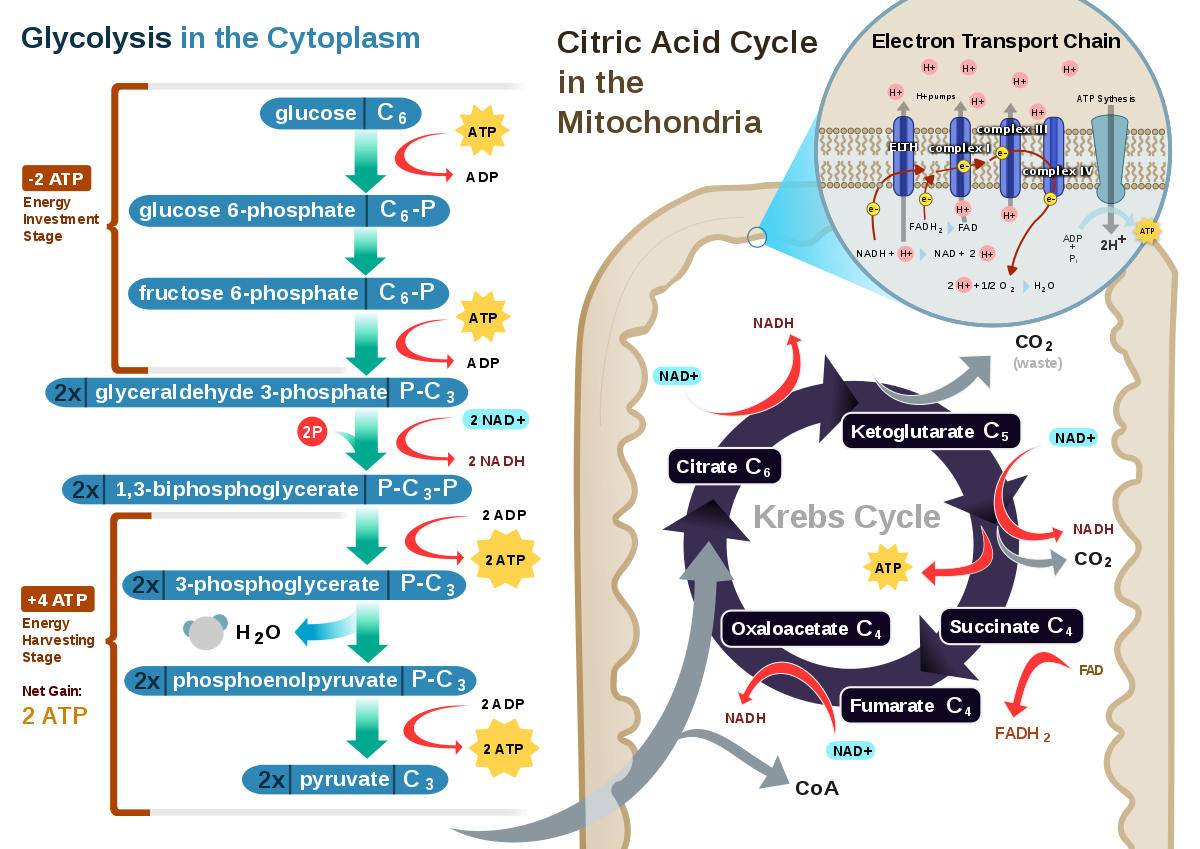

The glycolysis step alone requires ten enzymes to complete the conversion of glucose into pyruvate.

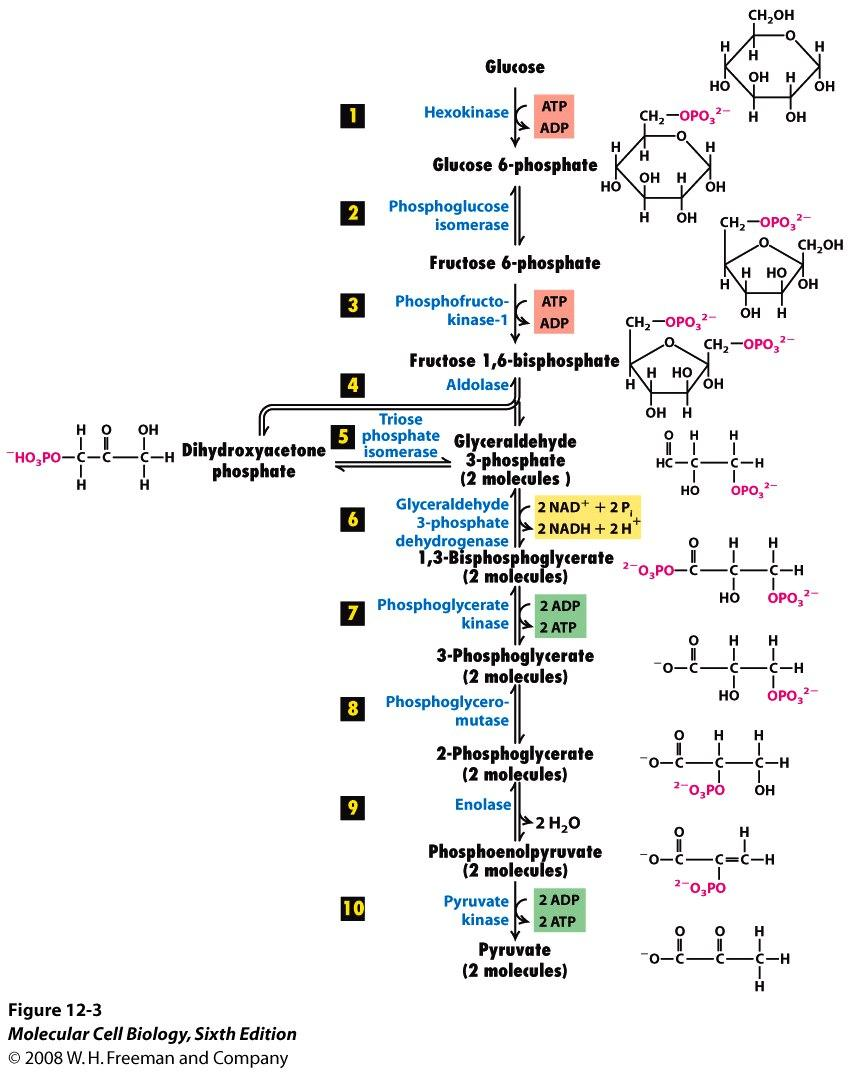

Therefore, this is an example of a chemical equation that summarizes a longer process. But what about the individual steps of the process? Chemical equations can be written for each of them as well.

Let's consider the first step of glycolysis: converting glucose (G) to α-D-Glucose-6-phosphate (J) by the enzyme hexokinase (E). This reaction can be described by the simple reaction below.

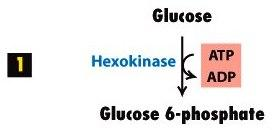

$G \rightarrow J$, or, $G+E \rightarrow J+E$

But even this equation doesn't show the whole story. There are different events that need to take place for G to end up as J. First, G has to bind the enzyme, then the enzyme has to catalyze the reaction. This is shown in the following network:


$$G+E \rightleftharpoons GE \rightarrow J+E$$


We can now see each of the steps of a single enzymatic reaction. Each of the other reactions involved in glycolysis could be linked with this reaction to form a much larger network to fully describe glycolysis. 

## Chemical rates

We have described the steps of a simple enzymatic process, but all of biochemistry depends on how fast reactions occur (particularly in relation to other reactions). So how fast do each of these steps occur? 

The network above has three possible reactions: G binding E, G unbinding E, and GE catalyzing to release J and E. We can describe how fast these reactions are by assigning them each a rate, $k$. 


$$G+E \underset{k_{\rm{off}}}{\stackrel{k_{\rm{on}}}{\rightleftharpoons}} GE \overset{k_{\rm{cat}}}{\rightarrow} J+E$$


Consider the a single step: $G + E \overset{k_{\rm{on}}}{\rightarrow} GE$

If we wanted to describe how the concentration of GE is changing with time, based on this single step, we could write down the equation:


$$dGE/dt = k_{on}$$


This equation assumes that there is some constant rate $k_\rm{on}$ at which the concentration of enzyme-substrate complex increases, regardless of any other factors.

But intuitively, **if there is no substrate** in the system, **how would you expect the concentration of GE to change with time**?

Similarly, if there is significantly less substrate than enzyme, how would you expect that to affect the concentration of GE compared to if there was as much substrate as enyzme (where the amount of enzyme is the same here)?

This intuition suggests that the rate the concentration of GE changes with time depends not only on how fast molecules bind to each other, but also how much of each of them is present or rather, how often they encounter each other. This concept is know as **Mass-Action Kinetics**.

## Mass-Action Kinetics

Under the assumption of mass-action kinetics, it is now possible to write down differential equations to describe how each *species* (G, J, E, GE) changes with time.


$$dG/dt = - k_{\rm{on}} \cdot G \cdot E + k_{\rm{off}} \cdot GE$$



$$dJ/dt = k_{\rm{cat}} \cdot GE$$



$$dE/dt = - k_{\rm{on}} \cdot G \cdot E + k_{\rm{off}} \cdot GE + k_{\rm{cat}} \cdot GE$$



$$dGE/dt = k_{\rm{on}} \cdot G \cdot E - k_{\rm{off}} \cdot GE - k_{\rm{cat}} \cdot GE$$


Things to note: the *total* enzyme concentration should never change (look at E+GE).  Given this, we can rewrite these equations with $E_{\rm{Total}} = E + GE$, reducing our system of equations to only three:


$$dG/dt = - k_{\rm{on}} \cdot G \cdot (E_{\rm{Tot}} - GE) + k_{\rm{off}} \cdot GE$$



$$dJ/dt = k_{\rm{cat}} \cdot GE$$



$$dGE/dt = k_{\rm{on}} \cdot G \cdot (E_{\rm{Tot}} - GE) - k_{\rm{off}} \cdot GE - k_{\rm{cat}} \cdot GE$$


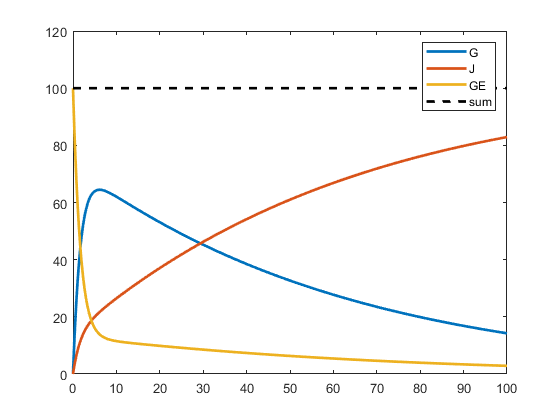

% set up initial conditions
ETot = 100;
G0 = 0;
J0 = 0;

% set rates
kon = 0.001;
koff = 0.4;
kcat = 0.1;

% create differential equations
dGdt = @(G,J,GE) -kon*G*(ETot-GE) + koff*GE;
dJdt = @(G,J,GE) kcat*GE;
dGEdt =  @(G,J,GE) kon*G*(ETot-GE) - koff*GE - kcat*GE;

dxdt = @(t,x) [ dGdt(x(1),x(2),x(3));
        dJdt(x(1),x(2),x(3));
        dGEdt(x(1),x(2),x(3)) ];
    
% solve system
[T,X] = ode45(dxdt,[0,100],[G0,J0,ETot]);

%% plot
figure(1); clf; hold on; box on;
plot(T,X,'LineWidth',2);
plot(T,sum(X,2),'--k','LineWidth',2);

legend('G', 'J', 'GE','sum');